close all;clear all;clc
% Set up communications
arduino=serialport("/dev/cu.usbmodem141301",9600,"Timeout",15) 

arduino = Serialport with properties

                 Port: "/dev/cu.usbmodem141301"
             BaudRate: 9600
    NumBytesAvailable: 0
      NumBytesWritten: 0

Show all properties


pause(1)
x = 0:255;
y = zeros(1,256);
for K=0:255
    flush(arduino)
    write(arduino,2,'string')
    pause(0.5)
    a=read(arduino,4,'string');
    flush(arduino)
    y(K+1)=str2double(a);
    disp([K,y(K+1)])
end 

     0   299

     1   298

     2   399

     3   NaN

     4   490

     5   NaN

     6   524

     7   NaN

     8   582

     9   602

    10   648

    11   NaN

    12   638

    13   NaN

    14   683

    15   661

    16   676

    17   702

    18   711

    19   NaN

    20   733

    21   NaN

    22   732

    23   NaN

    24   767

    25   747

    26   756

    27   776

    28   NaN

    29   761

    30   NaN

    31   784

    32   787

    33   821

    34   791

    35   792

    36   NaN

    37   818

    38   NaN

    39   798

    40   811

    41   820

    42   802

    43   839

    44   NaN

    45   822

    46   NaN

    47   849

    48   826

    49   824

    50   851

    51   846

    52   NaN

    53   851

    54   NaN

    55   846

    56   858

    57   872

    58   848



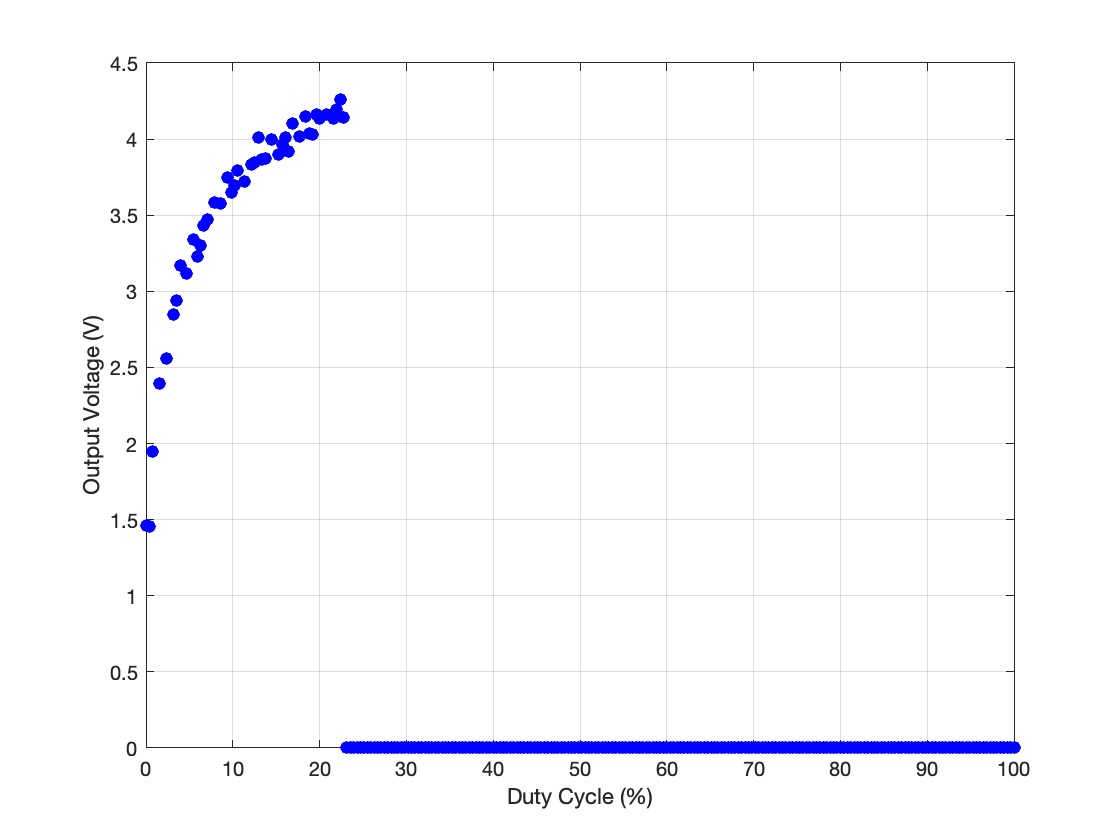

delete(arduino);
clear arduino;
figure 
plot(x/255*100,y*5/1023,'bo','MarkerFaceColor','blue') 
grid on
xlabel('Duty Cycle (%)')
ylabel('Output Voltage (V)')